# Service Ceiling Requirements

clc
clear all
% Pre-script
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'tex');
end

## plotting Parameters

PowerLoad_max_plot = .2; % N/W
WingLoad_max_plot = 600; % N/m^2
n_plotPoints = 100;

## Generating Code

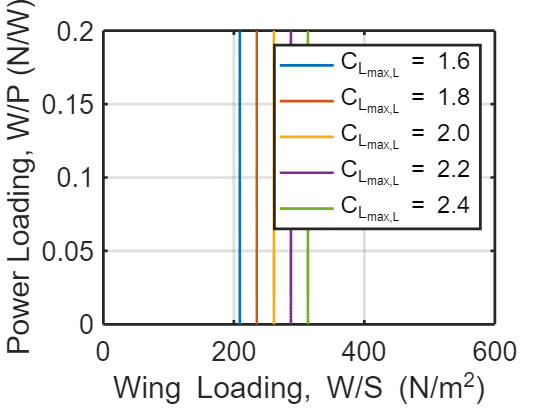



rho_1 = 1.225; % Density at sea level kg/m^3
T_1C = 15; % Standard temperature at sea level in C
p_1 = 101325; % Standard sea level pressure in Pa
C_LmaxL = [1.6, 1.8, 2.0, 2.2, 2.4]; % C_LmaxL range of values
WL2WTO = 1; % Landing weight to take off weight ratio
S_L = 250; % Landing distance in m
S_L = 500; % Landing distance in m

S_LG = S_L/1.938; % Landing ground distance in m
S_LGft = convlength(S_LG,'m','ft'); % Convert m to ft
V_SLkts = sqrt(S_LGft/0.265); % Landing stall speed in kts
V_SL = (1852/3600)*V_SLkts; % Convert kts to m/s
V_A = 1.3 * V_SL; % Approach speed in m/s from CS22

% Items of note
% Landing configuration stall speeds (V_SL)v must never exceed
%   22.2 m/s with retracted air brakes, maximum weight, and empty water ballast tanks
%   25 m/s with retracted air brakes, maximum weight, with water in ballast tanks
%   26.4 m/s with deployed air brakes, maximum weight, with water in ballast tanks

%Find rho_2 at ISA+10C
T_1 = T_1C + 273.15; % Convert Celcius to Kelvin
T_2 = T_1 + 10 + 273.15; % ISA temp +10C in K
p_2 = p_1; % Pressure at ISA+10C
rho_2 = rho_1 * (T_1/T_2); % Density at ISA +10C in kg/m^3

W2S = (0.5 .* rho_2 .* V_SL^2 .* C_LmaxL) ./ WL2WTO;

W2P = linspace(0,PowerLoad_max_plot,n_plotPoints);
W2S_L1 = ones(size(W2P)) .* W2S(1,1); 
W2S_L2 = ones(size(W2P)) .* W2S(1,2);
W2S_L3 = ones(size(W2P)) .* W2S(1,3); 
W2S_L4 = ones(size(W2P)) .* W2S(1,4);
W2S_L5 = ones(size(W2P)) .* W2S(1,5);


plot(W2S_L1,W2P, 'DisplayName', "C_{L_{max,L}} = 1.6", LineWidth=1.5);
hold on
plot(W2S_L2,W2P, 'DisplayName', "C_{L_{max,L}} = 1.8", LineWidth=1.5);
hold on
plot(W2S_L3,W2P, 'DisplayName', "C_{L_{max,L}} = 2.0", LineWidth=1.5);
hold on
plot(W2S_L4,W2P, 'DisplayName', "C_{L_{max,L}} = 2.2", LineWidth=1.5);
hold on
plot(W2S_L5,W2P, 'DisplayName', "C_{L_{max,L}} = 2.4", LineWidth=1.5);

% compute values
for i = 1:5
    W2S_A(:,i) = linspace(W2S(i), WingLoad_max_plot, 2);
end

% % plot
% area(W2S_A(:,1), ones([2,1]) * W2S(1), "FaceAlpha",.10, "FaceColor",[0,1,0], "LineStyle","none", 'DisplayName', "Verboden by Landing Requirements")
% for i = 2:5
%     area(W2S_A(:,i), ones([2,i]) * W2S(1), "FaceAlpha",.10, "FaceColor",[0,1,0], "LineStyle","none", 'HandleVisibility','off');
% end

xlabel("Wing Loading, W/S (N/m^2)", "Interpreter","tex", "FontSize",15);
ylabel("Power Loading, W/P (N/W)", "Interpreter","tex", "FontSize",15);
xlim([0, WingLoad_max_plot]);
ylim([0, PowerLoad_max_plot]);


%legend('C_{LmaxL} = 1.6','C_{LmaxL} = 1.8','C_{LmaxL} = 2.0','C_{LmaxL} = 2.2','C_{LmaxL} = 2.4', Location="northwest")
legend show;
%legend("Interpreter","tex", "FontSize",12, Orientation="horizontal", Location="south");

grid on;
set(gca, 'LineWidth',1.5);
set(gca, 'FontSize',15);
hold on

## CEiling Requirements

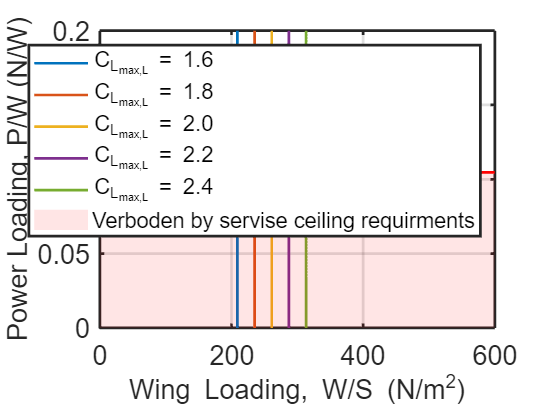



L_Dmax = 46.5; % L/D max
A = 22.82; % Aspect ratio
e = 1; % Oswald's efficiency factor
eta_p = 0.8; % Prop efficiency, based on modern high efficient props
W2S = linspace(0, WingLoad_max_plot, n_plotPoints); % Range of wing loadings in N/m^2
T_1 = 15; % Sea level temperature in C
sigma_7500 = 0.79826; % Density ratio at 7500 ft (mid point of climb) according to U.S. Standard Atmosphere 1976
% note to selfe, use atmoISA to find density ratio at altitude and divid by sea level
h = 14000; % Service ceiling in ft
h_abs = 15000; % Absolute ceiling in ft
RC_h = 100; % Rate of climb at altitude in ft/min, 100 ft/min chosen for service ceiling

% Find Rate of Climb at Sea Level
RC_0 = RC_h / (1 - (h/h_abs)); % Estimated rate of climb at sea level ft/min

% Find C_D0 to calculate C_LRCmax
C_Lmax = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
C_Dmax = 2 * (C_Lmax^2)/(pi * A * e); % Maximum drag coefficient
C_D0 = C_Dmax / 2; % Parasite drag coefficient

C_LRCmax = sqrt(3 * C_D0 * pi * A * e); % Maximum rate of climb lift coefficient

% Find C_DRCmax to find (C_L^3/2 / C_D)_max
C_DRCmax = 4 * C_D0; % Maximum rate of climb drag coefficient
%C_L32C_Dmax = (1.345 * (A * e)^(3/4)) / (C_D0^(1/4)); % C_L^3/2 / C_D
C_L32C_Dmax = (C_LRCmax^(3/2))/C_DRCmax;

% Find density ratio for mid point of climb + 10C
T_2 = (T_1 + 10 + 273.15); % Sea level temperature + 10C
sigma_ISA10 = (T_1 + 273.15) / (T_1 + 273.15); % Density ratio for ISA + 10C
sigma_7500_10 = sigma_ISA10 * sigma_7500; % Density ratio for 7500 ft + 10C

% Calculate RCP and substitute in power loading equation
RCP_EngU = RC_0/33000; % Rate of climb parameter hp/lbf
RCP = RCP_EngU * (745.7/4.45); % Rate of climb parameter in W/N

W2P = eta_p./(RCP + (sqrt(W2S)./(19 .* sqrt(sigma_7500_10) .* C_L32C_Dmax))); % Power loading N/W

% plotting

plot(W2S, W2P, "r", LineWidth=1.5, HandleVisibility="off"); hold on
area(W2S, W2P, "FaceAlpha",.10, "FaceColor",[1,0,0], "LineStyle","none", "DisplayName", "Verboden by servise ceiling requirments");

grid on;
set(gca, 'LineWidth',1.5);
set(gca, 'FontSize',15);

xlabel("Wing Loading, W/S (N/m^2)", "Interpreter","tex", "FontSize",15);
ylabel("Power Loading, P/W (N/W)", "Interpreter","tex", "FontSize",15);

legend show;
legend("Interpreter","tex", "FontSize",12)

xlim([0, WingLoad_max_plot]);
ylim([0,PowerLoad_max_plot]);
hold on

## takeoff requirements

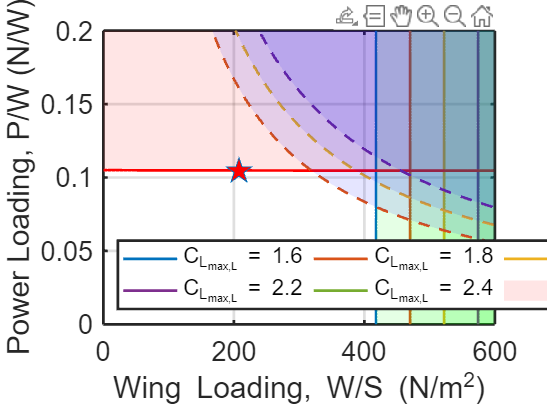

% re plot landingplot
area(W2S_A(:,1), ones([2,1]) * W2S(1), "FaceAlpha",.10, "FaceColor",[0,1,0], "LineStyle","none", 'DisplayName', "Verboden by Landing Requirements")
for i = 2:5
    area(W2S_A(:,i), ones([2,i]) * W2S(1), "FaceAlpha",.10, "FaceColor",[0,1,0], "LineStyle","none", 'HandleVisibility','off');
end

%% generating code

% Sizing to TO
W_to_max=2180;        %Max takeoff weight in lbs from intial sizing
We=1020;                %empty weight in lbs
S=174;                %Average wing area from STAMPED in ft^2
S_to_max=1640;       %Max takeoff distance in meters from CS 22 (= 500 m)
S_tog_max = S_to_max/1.6;    %From Fig 3.4 pg 96, S_tog from S_to
TOP23=86;                 %Eq 3.6, in lbs^2/(ft^2hp)
CL_max_to= linspace(1.4,2,3);
sigma_1000 = .9711;
sigma_1000_10 = sigma_1000 * sigma_ISA10;
sigma = sigma_1000_10;  % denisty ratio at ISA 1000ft + 10C
WS_to=linspace(We/S /2, W_to_max*1.5/S, 500);
WP_to1=TOP23*sigma*CL_max_to(:,1)./(WS_to);
WP_to2=TOP23*sigma*CL_max_to(:,2)./(WS_to);
WP_to3=TOP23*sigma*CL_max_to(:,3)./(WS_to);

% conver Wing Loading to SI Units
WSconvert = convforce(1,"lbf","N") / convlength(1,"ft","m")^2;
WS_to = WS_to * WSconvert;

% convert Power Loading to SI units
WPconvert = convforce(1,"lbf","N") / 745.7; % lbf/hp -> N/W
WP_to1 = WP_to1 * WPconvert;
WP_to2 = WP_to2 * WPconvert;
WP_to3 = WP_to3 * WPconvert;

plot(WS_to,WP_to1, "--", DisplayName='C_L_T_O=1.4', LineWidth=1.5); hold on;
plot(WS_to,WP_to2, "--", DisplayName='C_L_T_O=1.7', LineWidth=1.5);
plot(WS_to,WP_to3, "--", DisplayName='C_L_T_O=2.0', LineWidth=1.5);

area(WS_to, WP_to1, PowerLoad_max_plot, "FaceAlpha",.10, "FaceColor",[0,0,1], "LineStyle","none", DisplayName='Verboden by Takeoff Contraint'); hold on;
area(WS_to, WP_to2, PowerLoad_max_plot, "FaceAlpha",.10, "FaceColor",[0,0,1], "LineStyle","none", 'HandleVisibility','off');
area(WS_to, WP_to3, PowerLoad_max_plot, "FaceAlpha",.10, "FaceColor",[0,0,1], "LineStyle","none", 'HandleVisibility','off');

hold on
xline(W_to_max/S * WSconvert, "-", "Wing Loading at MTOW", 'HandleVisibility','off', "FontSize",12, LineWidth=1.5)

% plot design point
plot(209,.1047,'p', 'MarkerFaceColor','red', 'MarkerSize',15,  DisplayName='Design Point')

legend(Location="southwest")
legend("Interpreter","tex", "FontSize",12)
grid on;
set(gca, 'LineWidth',1.5);
set(gca, 'FontSize',15);
legend(Orientation="horizontal");
legend(NumColumns=3) % 2 wasnt bad